%calculating the mean first passage time analytically/numerically 
%to investigate effect of invader toehold length on RNA/DNA TMSD kinetics
%including spontaneous incumbent dissociation

b = 20 %define branch migration domain length 

b = 20

%g = 2 %define invader toehold length

R = 1.987/1000 %universal gas constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGrd = -0*R*temp

dGrd = 0

dGp = 3.6*R*temp

dGp = 2.1327

dGbm = 7.4*R*temp

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

k_eff = zeros(6,15)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(6, 15)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(6, 15)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through dGrd values
for dG = 0 :-0.2:-1
    dGrd = dG*R*temp
    %loop through invader toehold lengths 
    for g = 1:15 

        %define forward and reverse transition rates
        k_AA = 0;
        k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
        k_B1A = k_bp * exp((dGbp + dGrd)/(R*temp))
        k_BC1ij = k_bp;
        k_BC1ji = k_bp * exp((dGbp + dGrd)/(R*temp))
        k_C1f = k_bp * exp(-(dGbm + dGp)/(R*temp))
        k_Cf = k_bp * exp(-dGbm/(R*temp))
        k_Cr = k_bp * exp(-(dGbm - dGrd)/(R*temp))
        k_CD = k_bp * exp(-dGbm/(R*temp));
        k_DC = 0 
        k_DD = 1
    
        if g == 1
            %create arrays of forward and reverse transition rates
            Kf = [k_DD, k_CD, repmat(k_Cf, [1, b-2]), k_C1f, k_AB1]
            Kb = [k_DC, repmat(k_Cr, [1, b-2]), k_Cr, k_B1A, k_AA]
        
            %define spontaneous incumbent dissociation rates
            Koff = [0]; 
            for n = 1:b-1
                Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
            end
            Koff = horzcat(Koff, [0, 0])
        else
            %create arrays of forward and reverse transition rates
            Kf = [k_DD, k_CD, repmat(k_Cf, [1, b-2]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
            Kb = [k_DC, repmat(k_Cr, [1, b-2]), k_Cr, k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    
            %define spontaneous incumbent dissociation rates
            Koff = [0]; 
            for n = 1:b-1
                Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
            end
            Koff = horzcat(Koff, [repmat(0, [1, g+1])])
        end
    
        Pn_jN_1 = zeros(1,numel(Kf))
        jn_jN_1 = zeros(1,numel(Kf))
        Pn_jN_1 (1) = 0;
        jn_jN_1 (1) = 1;
        
        %calculate flux between each state
        for Pn = 2:numel(Kf)
            Pn_jN_1(Pn)  = 1/Kf(Pn) * jn_jN_1 (Pn-1) + (Kb(Pn-1)/Kf(Pn))*Pn_jN_1(Pn-1);
            jn_jN_1(Pn) = jn_jN_1(Pn-1) + Koff(Pn) * Pn_jN_1(Pn);
        end
        first_pass_time (round(-dG*5 + 1), g) = (1/jn_jN_1(end-1))*sum(Pn_jN_1) %calculate first passage time
        k_eff (round(-dG*5 + 1), g) = 1/(first_pass_time (round(-dG*5 + 1), g)*(5*10^-8)); %calculate effective rate constant
        prob_unbound (round(-dG*5 + 1), g) = Pn_jN_1(end)/sum(Pn_jN_1) %calculate probability of being in unbound state
    end
end

dGrd = 0

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_BC1ji = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 3.3008e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+04 *

    0.0001    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    0.0902    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448         0


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

    4.1740         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_BC1ji = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 3.3008e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448         0


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

    4.1740    0.3359         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_BC1ji = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 3.3008e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448         0


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

    4.1740    0.3359    0.0271         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_BC1ji = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 3.3008e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448         0


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

    4.1740    0.3359    0.0271    0.0022         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_BC1ji = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 3.3008e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

    4.1740    0.3359    0.0271    0.0022    0.0002         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_BC1ji = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 3.3008e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

    4.1740    0.3359    0.0271    0.0022    0.0002    0.0001         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_BC1ji = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 3.3008e+04

k_DC = 0

k_DD = 1

Kf = 	1.0e+07 *

    0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+06 *

         0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff = 	1.0e+06 *

         0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = 	1.0e+05 *

    4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_BC1ji = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_BC1ji = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_BC1ji = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_BC1ji = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_BC1ji = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_BC1ji = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_BC1ji = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_BC1ji = 4.3448e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 3.3008e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    0.0330    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448    4.3448


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


dGrd = -0.1185

k_AB1 = 0.2005

k_B1A = 3.5572e+06

k_BC1ji = 3.5572e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0001    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    0.0902    0.0000


Kb =          0    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    3.5572         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.5572e+06

k_BC1ji = 3.5572e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb =          0    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    3.5572    3.5572         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.5572e+06

k_BC1ji = 3.5572e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    3.5572    3.5572    3.5572         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.5572e+06

k_BC1ji = 3.5572e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    3.5572    3.5572    3.5572    3.5572         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.5572e+06

k_BC1ji = 3.5572e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    3.5572    3.5572    3.5572    3.5572    3.5572         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.5572e+06

k_BC1ji = 3.5572e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.5572e+06

k_BC1ji = 3.5572e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.5572e+06

k_BC1ji = 3.5572e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.5572e+06

k_BC1ji = 3.5572e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.5572e+06

k_BC1ji = 3.5572e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.5572e+06

k_BC1ji = 3.5572e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.5572e+06

k_BC1ji = 3.5572e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.5572e+06

k_BC1ji = 3.5572e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.5572e+06

k_BC1ji = 3.5572e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 3.5572e+06

k_BC1ji = 3.5572e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.7024e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


dGrd = -0.2370

k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_BC1ji = 2.9124e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0001    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    0.0902    0.0000


Kb =          0    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    2.9124         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_BC1ji = 2.9124e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb =          0    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    2.9124    2.9124         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_BC1ji = 2.9124e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    2.9124    2.9124    2.9124         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_BC1ji = 2.9124e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    2.9124    2.9124    2.9124    2.9124         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_BC1ji = 2.9124e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    2.9124    2.9124    2.9124    2.9124    2.9124         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_BC1ji = 2.9124e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_BC1ji = 2.9124e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_BC1ji = 2.9124e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_BC1ji = 2.9124e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_BC1ji = 2.9124e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_BC1ji = 2.9124e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_BC1ji = 2.9124e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_BC1ji = 2.9124e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_BC1ji = 2.9124e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.9124e+06

k_BC1ji = 2.9124e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 2.2126e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    0.0221    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124    2.9124


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


dGrd = -0.3555

k_AB1 = 0.2005

k_B1A = 2.3845e+06

k_BC1ji = 2.3845e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.8115e+04

k_DC = 0

k_DD = 1

Kf =     0.0001    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    0.0902    0.0000


Kb =          0    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    2.3845         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.3845e+06

k_BC1ji = 2.3845e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.8115e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb =          0    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    2.3845    2.3845         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.3845e+06

k_BC1ji = 2.3845e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.8115e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    2.3845    2.3845    2.3845         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.3845e+06

k_BC1ji = 2.3845e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.8115e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    2.3845    2.3845    2.3845    2.3845         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.3845e+06

k_BC1ji = 2.3845e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.8115e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    2.3845    2.3845    2.3845    2.3845    2.3845         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.3845e+06

k_BC1ji = 2.3845e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.8115e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.3845e+06

k_BC1ji = 2.3845e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.8115e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.3845e+06

k_BC1ji = 2.3845e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.8115e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.3845e+06

k_BC1ji = 2.3845e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.8115e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.3845e+06

k_BC1ji = 2.3845e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.8115e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.3845e+06

k_BC1ji = 2.3845e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.8115e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.3845e+06

k_BC1ji = 2.3845e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.8115e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.3845e+06

k_BC1ji = 2.3845e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.8115e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.3845e+06

k_BC1ji = 2.3845e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.8115e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 2.3845e+06

k_BC1ji = 2.3845e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.8115e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    0.0181    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845    2.3845


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


dGrd = -0.4739

k_AB1 = 0.2005

k_B1A = 1.9523e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0001    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    0.0902    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003    0.0001         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999    0.9995         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523    1.9523         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003    0.0001    0.0001         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999    0.9995    0.9994         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003    0.0001    0.0001    0.0001         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999    0.9995    0.9994    0.9994         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999    0.9995    0.9994    0.9994    0.9994         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999    0.9995    0.9994    0.9994    0.9994    0.9994         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999    0.9995    0.9994    0.9994    0.9994    0.9994    0.9994         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999    0.9995    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999    0.9995    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999    0.9995    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999    0.9995    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999    0.9995    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.9523e+06

k_BC1ji = 1.9523e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.4831e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    0.0148    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523    1.9523


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999    0.9995    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


dGrd = -0.5924

k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0001    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    3.3008    0.0902    0.0000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1399         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999    0.9995    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994
    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    0.0000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1399    0.0042         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999    0.9995    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994
    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    0.0000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984    1.5984         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1399    0.0042    0.0002         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999    0.9995    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994
    1.0000    1.0000    0.9999         0         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984    1.5984    1.5984         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1399    0.0042    0.0002    0.0001         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999    0.9995    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994
    1.0000    1.0000    0.9999    0.9995         0         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984    1.5984    1.5984    1.5984         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1399    0.0042    0.0002    0.0001    0.0001         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999    0.9995    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994
    1.0000    1.0000    0.9999    0.9995    0.9995         0         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1399    0.0042    0.0002    0.0001    0.0001    0.0001         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999    0.9995    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994
    1.0000    1.0000    0.9999    0.9995    0.9995    0.9995         0         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1399    0.0042    0.0002    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999    0.9995    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994
    1.0000    1.0000    0.9999    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1399    0.0042    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999    0.9995    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994
    1.0000    1.0000    0.9999    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984         0


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1399    0.0042    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999    0.9995    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994
    1.0000    1.0000    0.9999    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1399    0.0042    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999    0.9995    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994
    1.0000    1.0000    0.9999    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1399    0.0042    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999    0.9995    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994
    1.0000    1.0000    0.9999    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1399    0.0042    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999    0.9995    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994
    1.0000    1.0000    0.9999    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1399    0.0042    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999    0.9995    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994
    1.0000    1.0000    0.9999    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1399    0.0042    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999    0.9995    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994
    1.0000    1.0000    0.9999    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995         0


k_AB1 = 0.2005

k_B1A = 1.5984e+06

k_BC1ji = 1.5984e+06

k_C1f = 901.8918

k_Cf = 3.3008e+04

k_Cr = 1.2143e+04

k_DC = 0

k_DD = 1

Kf =     0.0000    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984    1.5984


Koff =          0    4.3448    0.3496    0.0281    0.0023    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time =     4.1740    0.3359    0.0271    0.0022    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    1.0512    0.0693    0.0046    0.0004    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.4880    0.0264    0.0015    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.2922    0.0130    0.0006    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1961    0.0071    0.0003    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1399    0.0042    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9989    0.9963    0.9955    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954    0.9954
    1.0000    1.0000    1.0000    0.9998    0.9989    0.9985    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984    0.9984
    1.0000    1.0000    1.0000    0.9996    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991    0.9991
    1.0000    1.0000    0.9999    0.9995    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993    0.9993
    1.0000    1.0000    0.9999    0.9995    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994    0.9994
    1.0000    1.0000    0.9999    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995    0.9995


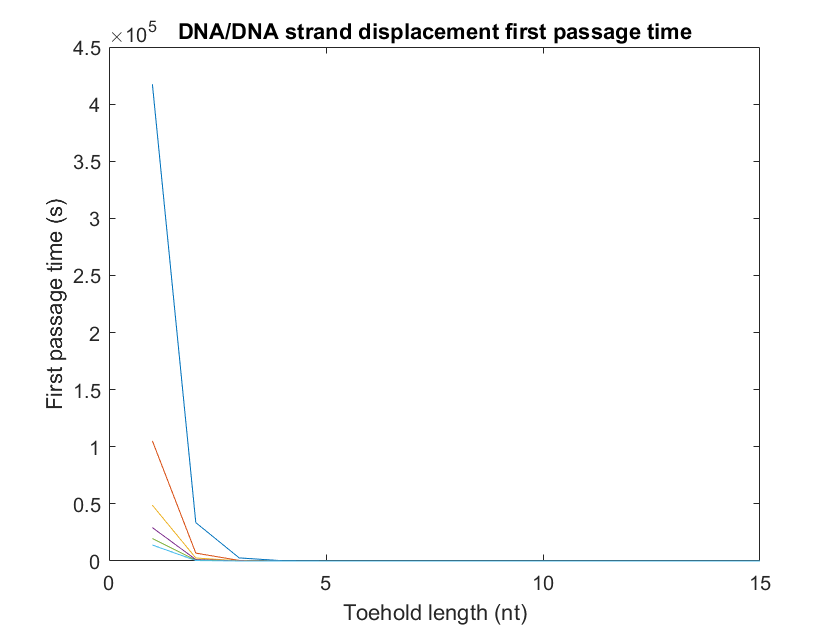

plot(1:15, first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

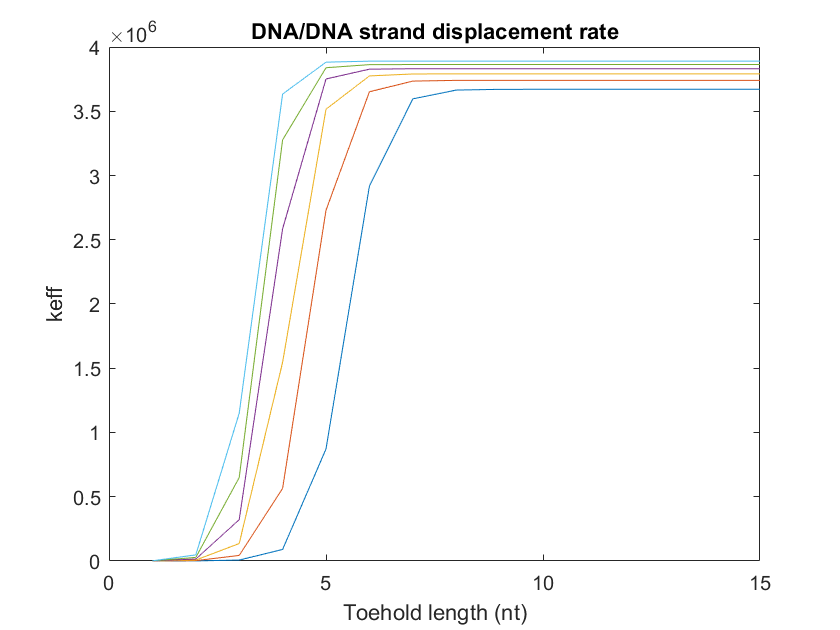


plot(1:15, k_eff)
xlabel('Toehold length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate')


ax = gca;
%dark_blue = 1/255*[31,120,180];
%medium_blue = 1/255*[95, 141, 211]
%light_blue  = 1/255*[146,197,222];
%rred = 1/255*[202,0,32];
%maroon = 1/255*[170, 0, 0]
%teal = 1/255*[55, 200, 171]
%purple = [0.4940, 0.1840, 0.5560]
%indigo = 1/255*[198, 175, 233]
%colour = [[rred]; [purple]; [indigo]; [dark_blue]; [medium_blue]; [light_blue]]

blue_1 = 1/255*[22, 45, 82];
blue_2 = 1/255*[38, 68, 156];
blue_3 = 1/255*[44, 125, 205];
blue_5 = 1/255*[162, 220, 239];
blue_4 = 1/255*[110, 186, 239];
blue_6 = 1/255*[190, 215, 225];
colour = [[blue_1]; [blue_2]; [blue_3]; [blue_4]; [blue_5]; [blue_6]]

colour =     0.0863    0.1765    0.3216
    0.1490    0.2667    0.6118
    0.1725    0.4902    0.8039
    0.4314    0.7294    0.9373
    0.6353    0.8627    0.9373
    0.7451    0.8431    0.8824



%map = colormap(autumn(6))
for dG = 1:6
    plot(1:15, log10(k_eff(dG, :)), 'Color', colour(dG, :), 'linewidth', 2)
    hold on
    scatter(1:15, log10(k_eff(dG, :)),[], colour(dG, :),  'filled', 'HandleVisibility', 'off')
end
legend('DNA', '-0.2RT','-0.4RT', '-0.6RT', '-0.8RT', '-1RT', 'location', 'southeast')
ax.LineWidth = 1.5

ax =   Axes with properties:

             XLim: [0 15]
             YLim: [1 7]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.YAxis.FontSize = 12

ax =   Axes with properties:

             XLim: [0 15]
             YLim: [1 7]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.XAxis.FontSize = 12

ax =   Axes with properties:

             XLim: [0 15]
             YLim: [1 7]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


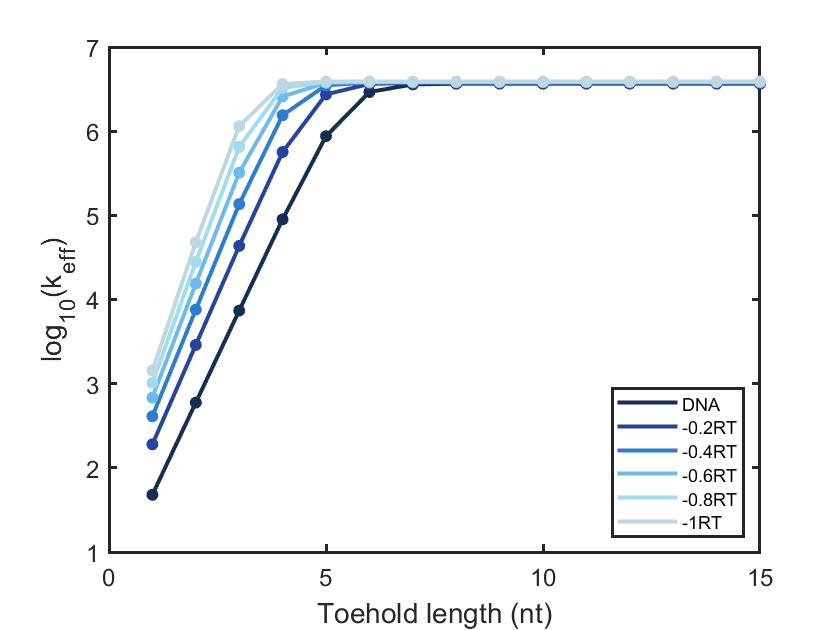

xlabel('Toehold length (nt)', 'FontSize', 14)
ylabel('log_1_0(k_e_f_f)', 'FontSize', 14)
hold off